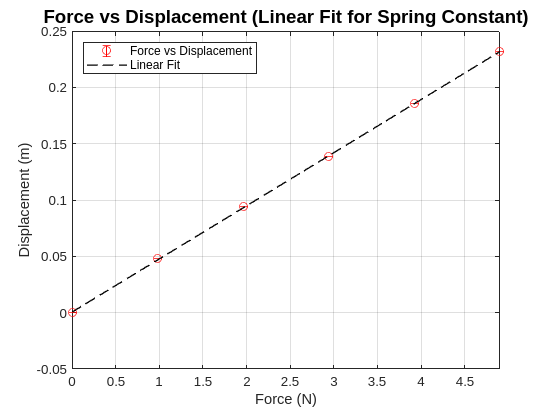


% -------------------------------------
% Linear Fit Part B
% -------------------------------------

% Prepare Data for Linear Fit
g = 9.81; % Acceleration due to gravity (m/s^2)
x = mass_weights * g; % x = force = mass * gravity
y = displacements;
w = 1 ./((pos_err_mean).^2); % Weights = 1 / (standard error mean)^2

% LSF: force vs position according to Hooke's Law (F = k * x)
[A, B, sigA, sigB] = linLSF_Derr(x, y, w);

% Calculate k from B (B = 1/k), and sigK, absolute value avoids complex numbers
k = abs(1 / B);     sigk = sigB / (B^2);

% Plot Linear Fit (Force vs Displacement) with error bars
figure; grid on; box on; hold on;
errorbar(x, displacements, pos_err_mean, 'ro', 'DisplayName', 'Force vs Displacement');

x_fit = linspace(min(x), max(x), 100);      y_fit = B * x_fit + A;
plot(x_fit, y_fit, 'k--', 'LineWidth', 1, 'DisplayName', 'Linear Fit');

xlabel('Force (N)', 'FontSize', 11); ylabel('Displacement (m)', 'FontSize', 11);
title('Force vs Displacement (Linear Fit for Spring Constant)', 'FontSize', 14);
legend('Location', 'northwest');
xlim([min(x), max(x)]);
hold off;


% Print the Results
fprintf('Parameters and Uncertainties y = Bx + A:\n');

Parameters and Uncertainties y = Bx + A:


fprintf('-------------------------------------------\n');

-------------------------------------------


fprintf('Intercept (A) = %.4f ± %.4f m\n', A, sigA);

Intercept (A) = 0.0005 ± 0.0000 m


fprintf('Slope (B) = %.4f ± %.4f 1/N\n', B, sigB);

Slope (B) = 0.0472 ± 0.0000 1/N


fprintf('Spring constant (k) = %.2f ± %.2f N/m\n', k, sigk);

Spring constant (k) = 21.21 ± 0.00 N/m


fprintf('-------------------------------------------\n');

-------------------------------------------
